addpath('../Library');
load('BGimg0223');
%Define the physical constant
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
warning('off','all');
[ KappaTildeT_U, PTildeT_U, TTildeT_U, ~, ~] = VirialUnitarity( );

filefolder_Unitary='/Users/Zhenjie/Data/2016-02-23/';

file1='02-23-2016_21_05_24_top';
[Pt,Kt,nsort,Vsort,Zsort,Ptsel,Ktsel,EF]=EOS_Online( [filefolder_Unitary,file1,'.fits'],'ROI1',[215,25,312,402],...
    'ROI2',[209,187,335,243],'ShowOutline',0,'TailRange',[85,325],'KappaMode',2,'PolyOrder',10,'VrangeFactor',5,'IfHalf',0,'kmax',1.1,'kmin',0.1,'Points',20,...
    'Fudge',2.92,'smooth',1,'CutOff',inf,'ShowPlot',0,'ShowOutline',0,'BGSubtraction',BGimg,'SelectByPortion',0,'Portion',0.1,...
    'IfTailTailor',1,'IfFitExpTail',1,'ExpTailPortion',0.06);

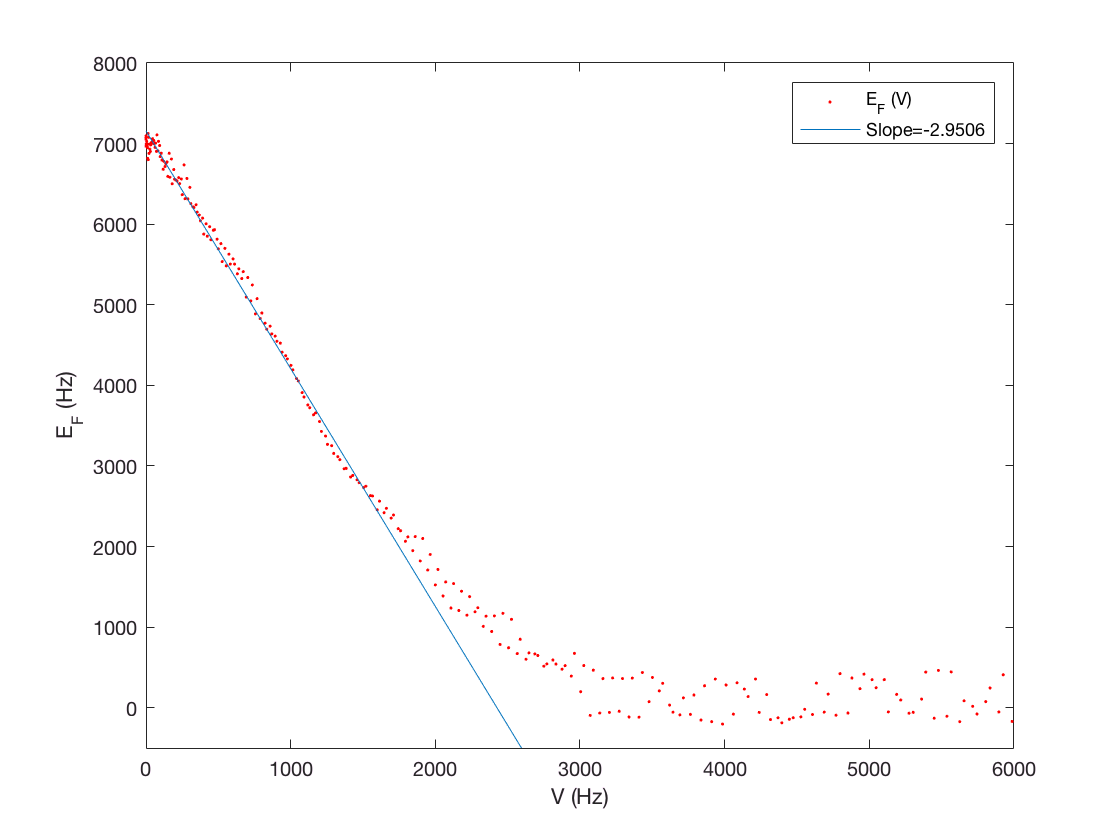

Vhz=Vsort/hh;
EFhz=EF/hh;
xlim([0,6000]);
Vfit=Vhz(Vhz<1500);
EFfit=EFhz(Vhz<1500);
p=polyfit(Vfit,EFfit,1);
EFline=polyval(p,Vhz);
plot(Vhz,EFhz,'r.','DisplayName','E_F (V)');
xlim([0,6000]);ylim([-500,8000]);
hold on
plot(Vhz,EFline,'DisplayName',['Slope=',num2str(p(1))]);
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');
legend('show');

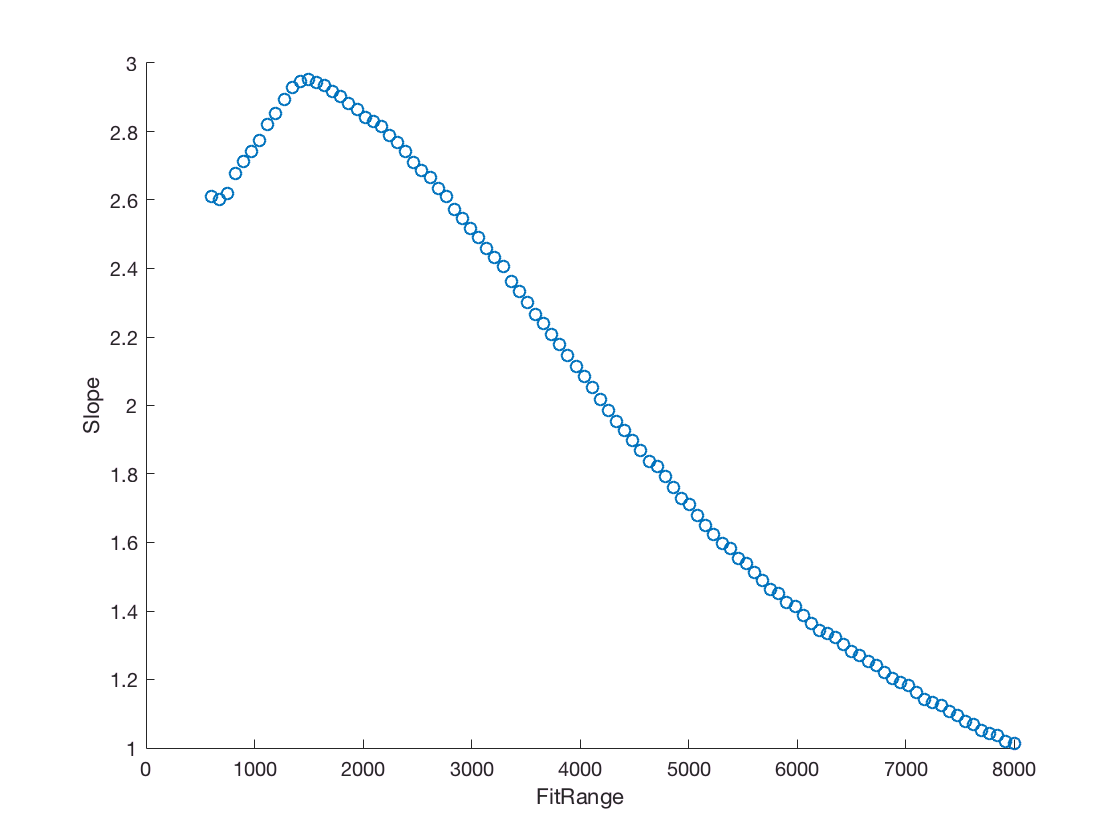

FitRange=linspace(600,8000,100);
N=length(FitRange);
slope=FitRange*0;
for i=1:N
    Vfit=Vhz(Vhz<FitRange(i));
    EFfit=EFhz(Vhz<FitRange(i));
    ptemp=polyfit(Vfit,EFfit,1);
    slope(i)=ptemp(1)*(-1);
end

scatter(FitRange,slope);
xlabel('FitRange');ylabel('Slope')

Try Simulated Data Set:

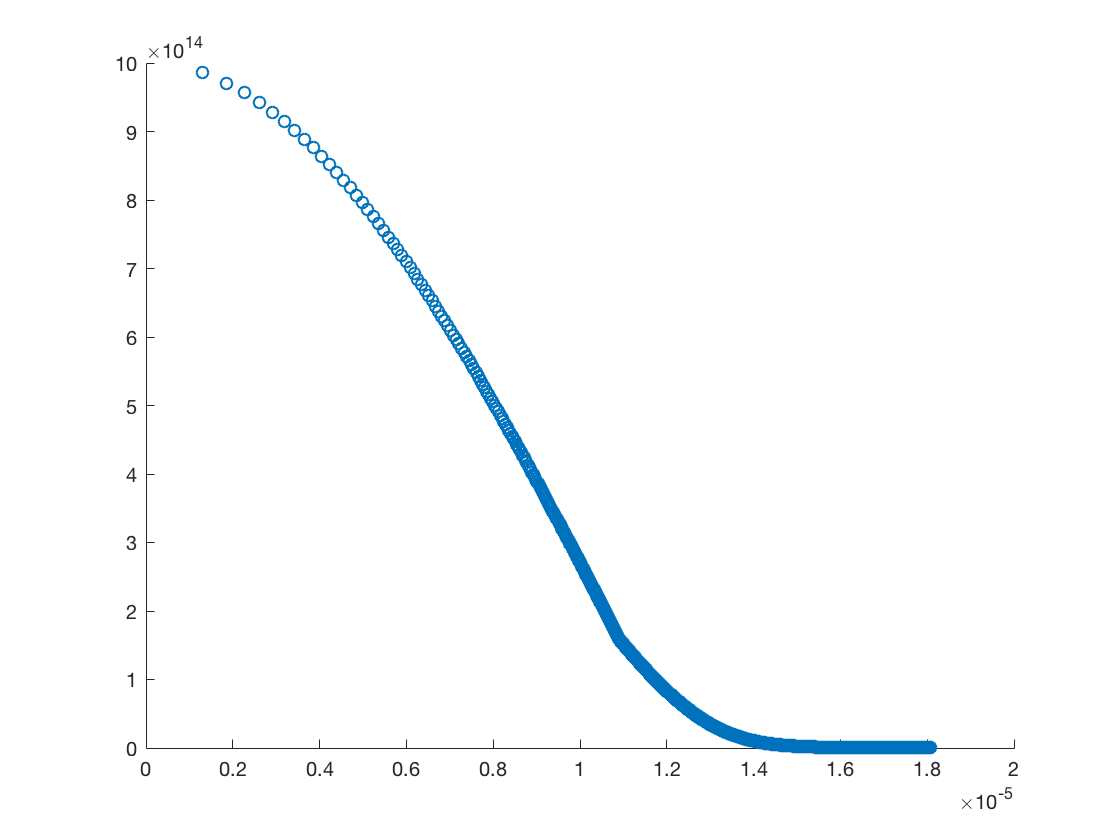

load('UnitaryFakeProfile.mat');
scatter(z_TTilde_vec,n_vec_TTilde);

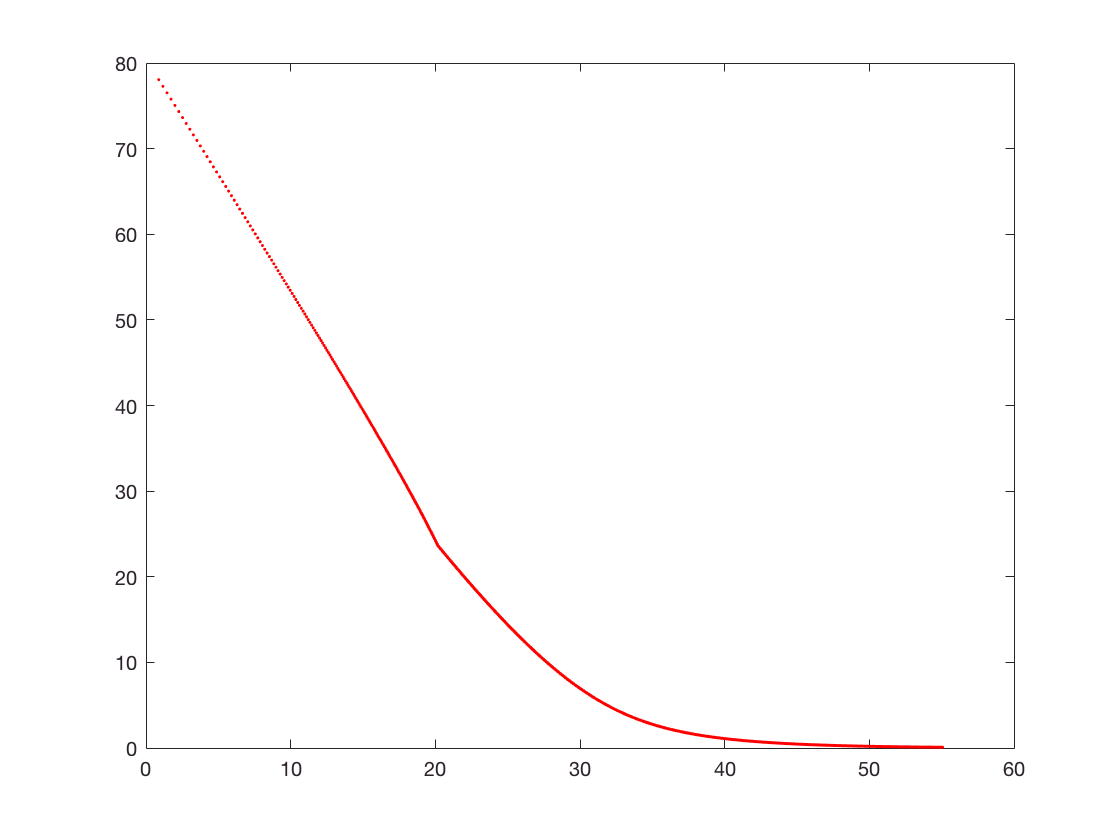

[zbin,nbin,~] = BinLinear(z_TTilde_vec,n_vec_TTilde,2e-6,1.8e-5,(1.8e-5)/5000 );
% zbin=z_TTilde_vec;nbin=n_vec_TTilde;
zbin(isnan(nbin))=[];
nbin(isnan(nbin))=[];
nbin=nbin/2;
Vbin=0.5*mli*omega^2*zbin.^2;
[Vsort,B]=sort(Vbin);
zsort=zbin(B);
nsort=nbin(B);
EF=hbar^2*(6*pi^2*nsort).^(2/3)/(2*mli);
EFhz=EF/hh;Vhz=Vsort/hh;
plot(Vhz,EFhz,'r.');

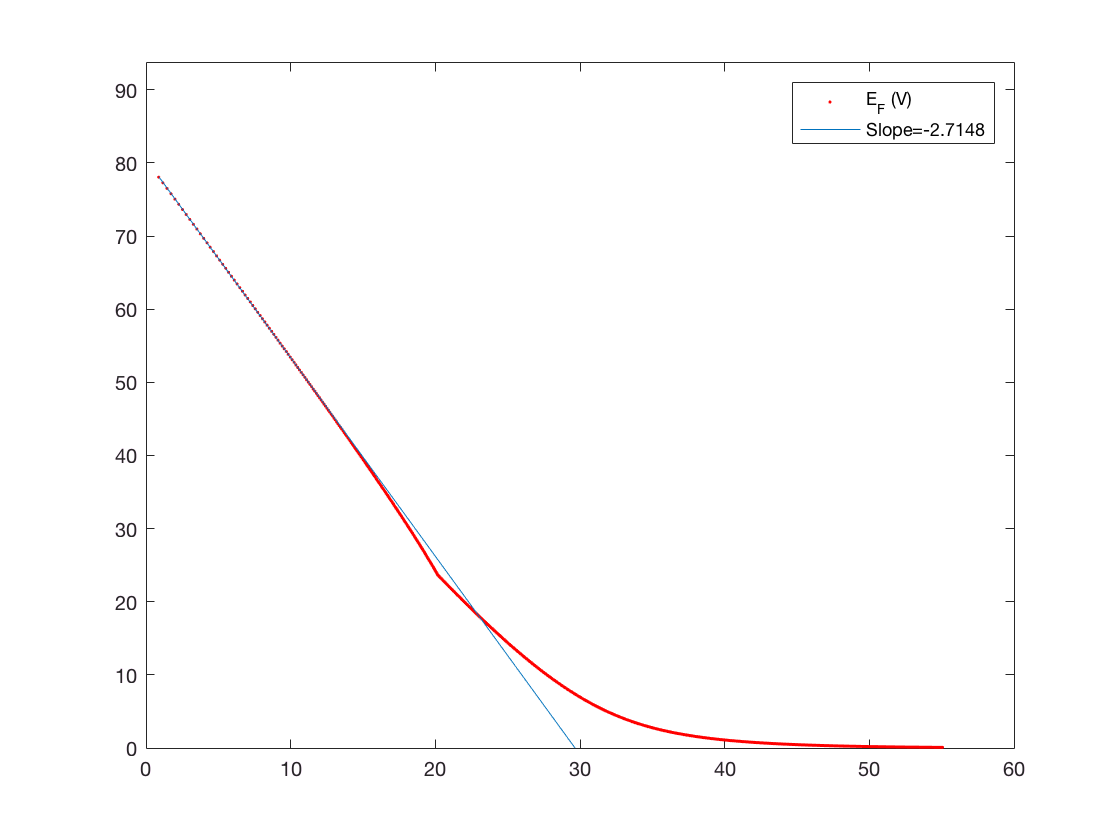

Vfit=Vhz(Vhz<12);
EFfit=EFhz(Vhz<12);
p=polyfit(Vfit,EFfit,1);
EFline=polyval(p,Vhz);
plot(Vhz,EFhz,'r.','DisplayName','E_F (V)');
hold on
plot(Vhz,EFline,'DisplayName',['Slope=',num2str(p(1))]);
hold off
ylim([0,max(EFhz)*1.2])
legend('show')

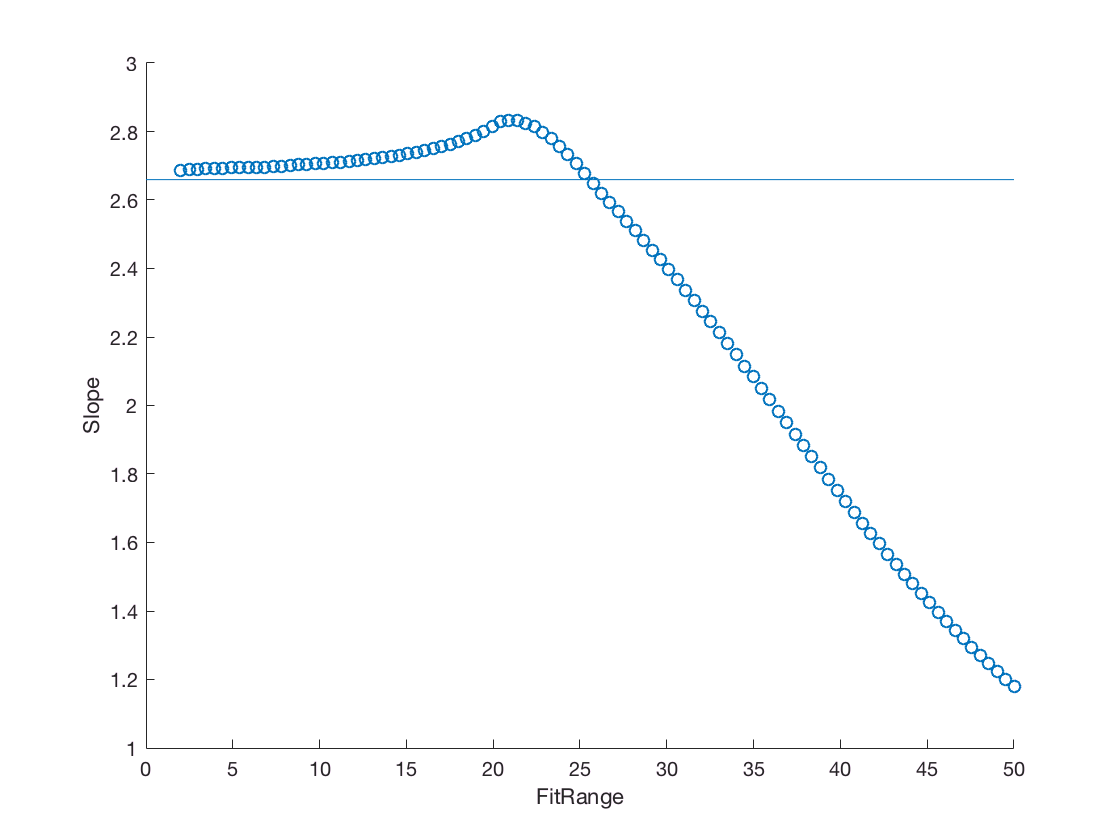

FitRange=linspace(2,50,100);
N=length(FitRange);
slope=FitRange*0;
for i=1:N
    Vfit=Vhz(Vhz<FitRange(i));
    EFfit=EFhz(Vhz<FitRange(i));
    ptemp=polyfit(Vfit,EFfit,1);
    slope(i)=ptemp(1)*(-1);
end

scatter(FitRange,slope);
xlabel('FitRange');ylabel('Slope')
hold on
line([0,max(FitRange)],[1/0.376,1/0.376]);
hold off

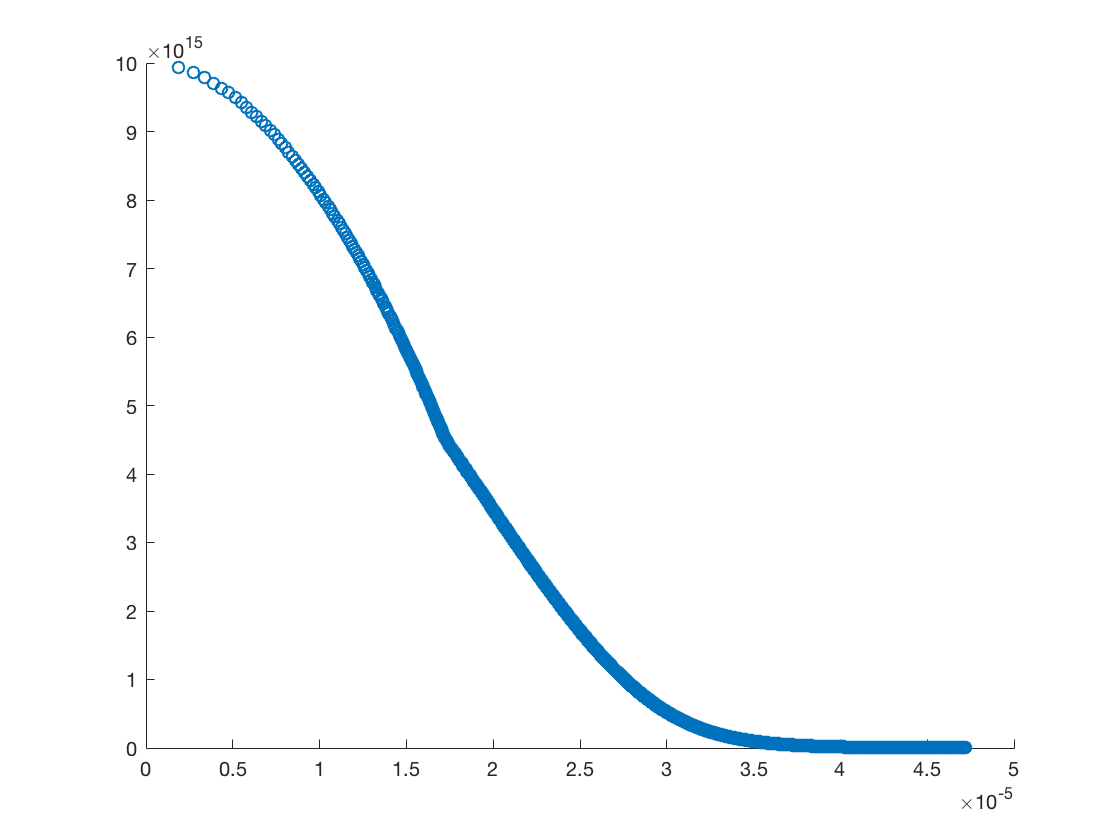

load('UnitaryFakeProfile_T0_1.mat');
scatter(z_TTilde_vec,n_vec_TTilde);

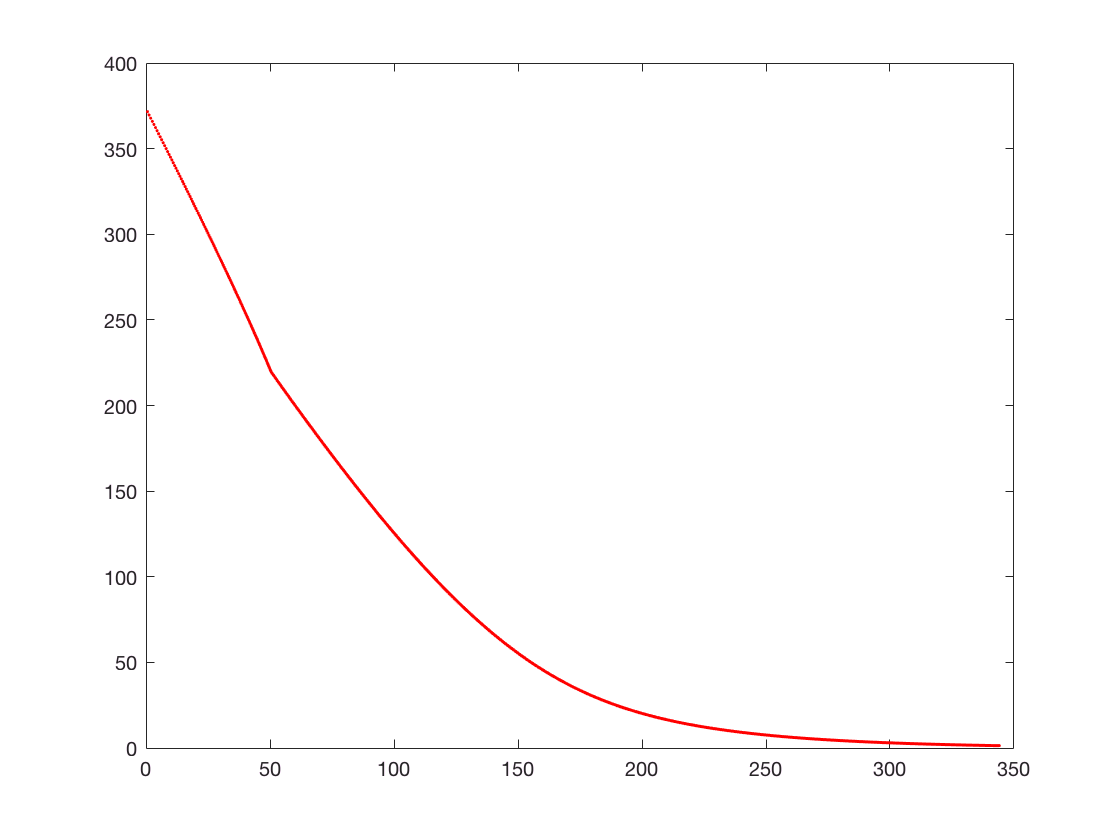

[zbin,nbin,~] = BinLinear(z_TTilde_vec,n_vec_TTilde,1e-6,4.5e-5,(4.5e-5)/5000 );
% zbin=z_TTilde_vec;nbin=n_vec_TTilde;
zbin(isnan(nbin))=[];
nbin(isnan(nbin))=[];
nbin=nbin/2;
Vbin=0.5*mli*omega^2*zbin.^2;
[Vsort,B]=sort(Vbin);
zsort=zbin(B);
nsort=nbin(B);
EF=hbar^2*(6*pi^2*nsort).^(2/3)/(2*mli);
EFhz=EF/hh;Vhz=Vsort/hh;
plot(Vhz,EFhz,'r.');

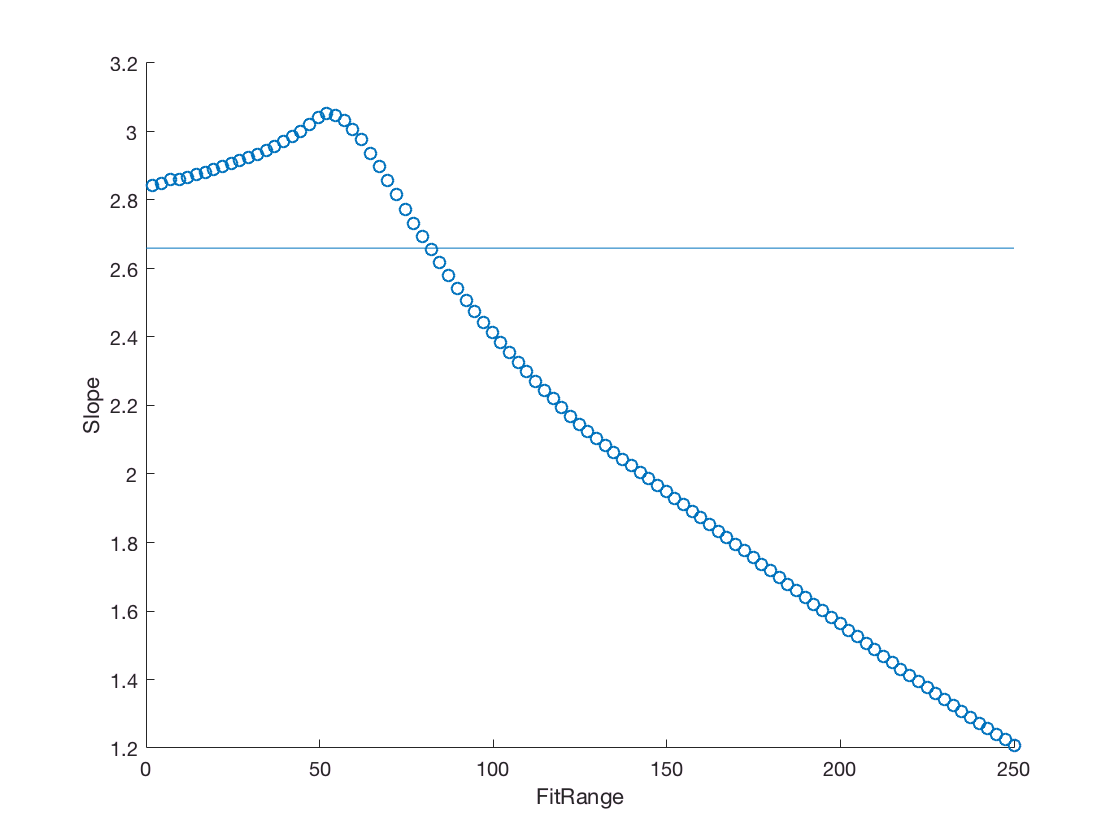

FitRange=linspace(2,250,100);
N=length(FitRange);
slope=FitRange*0;
for i=1:N
    Vfit=Vhz(Vhz<FitRange(i));
    EFfit=EFhz(Vhz<FitRange(i));
    ptemp=polyfit(Vfit,EFfit,1);
    slope(i)=ptemp(1)*(-1);
end

scatter(FitRange,slope);
xlabel('FitRange');ylabel('Slope')
hold on
line([0,max(FitRange)],[1/0.376,1/0.376]);
hold off

Plot the slope of the Unitary and the Polarized gas

filefolder_Unitary='/Users/Zhenjie/Data/2016-02-23/';
fileU='02-23-2016_21_05_24_top';
[~,~,~,VsortU,~,~,~,EFU]=EOS_Online( [filefolder_Unitary,file1,'.fits'],'ROI1',[215,25,312,402],...
    'ROI2',[209,187,335,243],'ShowOutline',0,'TailRange',[85,325],'KappaMode',2,'PolyOrder',10,'VrangeFactor',5,'IfHalf',0,'kmax',1.1,'kmin',0.1,'Points',20,...
    'Fudge',2.92,'smooth',1,'CutOff',inf,'ShowPlot',0,'ShowOutline',0,'BGSubtraction',BGimg,'SelectByPortion',0,'Portion',0.1,...
    'IfTailTailor',1,'IfFitExpTail',1,'ExpTailPortion',0.06);

filefolder_Polarized='/Users/Zhenjie/Data/2016-02-15/';
fileS1='02-15-2016_22_49_12_top';
[~,~,~,VsortS1,~,~,~,EFS1]=EOS_Online( [filefolder_Polarized,fileS1,'.fits'] ,'ROI1',[215,25,312,430],...
    'ROI2',[209,187,335,243],'ShowOutline',0,'TailRange',[60,380],'KappaMode',2,'PolyOrder',10,'VrangeFactor',5,'IfHalf',0,'kmax',0.9,'kmin',0.15,...
    'Fudge',2.62,'BGSubtraction',0,'IfFitExpTail',1,'Nsat',660,'ShowPlot',0);

fileS2='02-15-2016_22_52_33_top';
[~,~,~,VsortS2,~,~,~,EFS2]=EOS_Online( [filefolder_Polarized,fileS2,'.fits'] ,'ROI1',[215,25,312,430],...
    'ROI2',[209,187,335,243],'ShowOutline',0,'TailRange',[60,380],'KappaMode',2,'PolyOrder',10,'VrangeFactor',5,'IfHalf',0,'kmax',0.9,'kmin',0.15,...
    'Fudge',2.62,'BGSubtraction',0,'IfFitExpTail',1,'Nsat',660,'ShowPlot',0);


VsortU=VsortU/hh;EFU=EFU/hh;
VsortS1=VsortS1/hh;EFS1=EFS1/hh;
VsortS2=VsortS2/hh;EFS2=EFS2/hh;

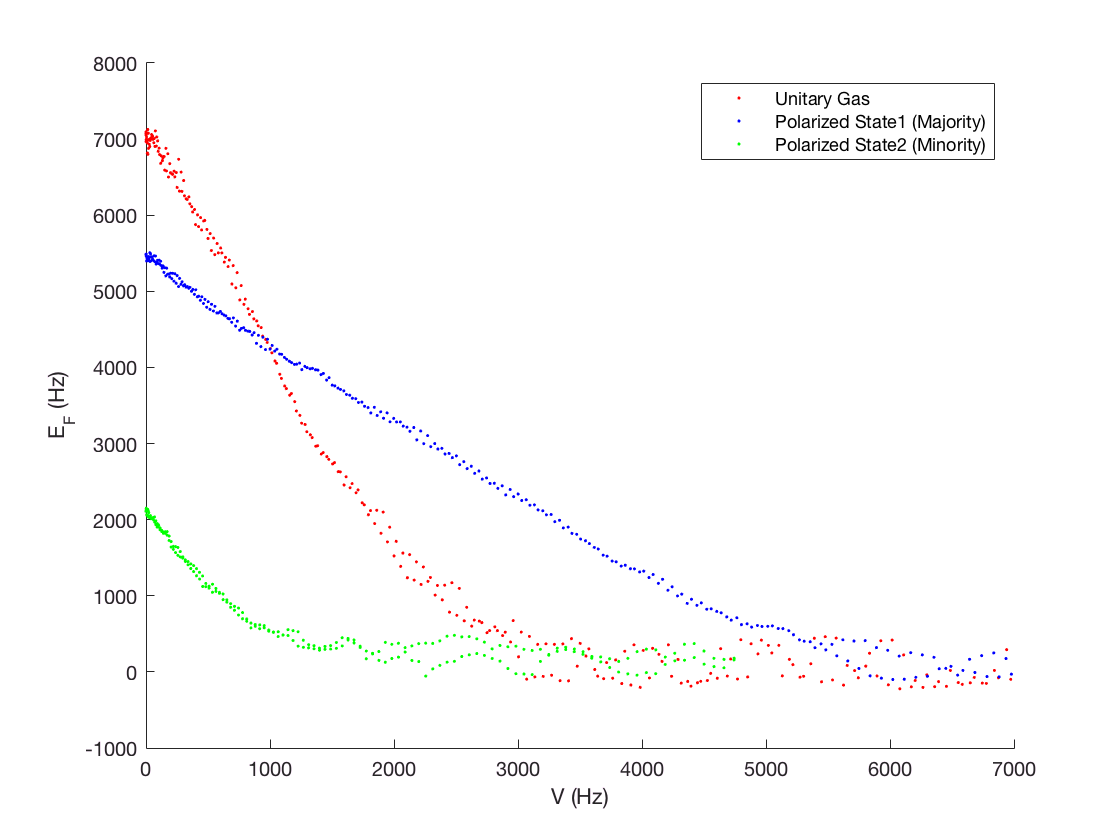

scatter(VsortU,EFU,'r.','DisplayName','Unitary Gas');
hold on
scatter(VsortS1,EFS1,'b.','DisplayName','Polarized State1 (Majority)');
scatter(VsortS2,EFS2,'g.','DisplayName','Polarized State2 (Minority)');
xlim([0,7000])
legend('Show')
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');

Then do the linear fitting to the unitary gas and polarized gas (majority)

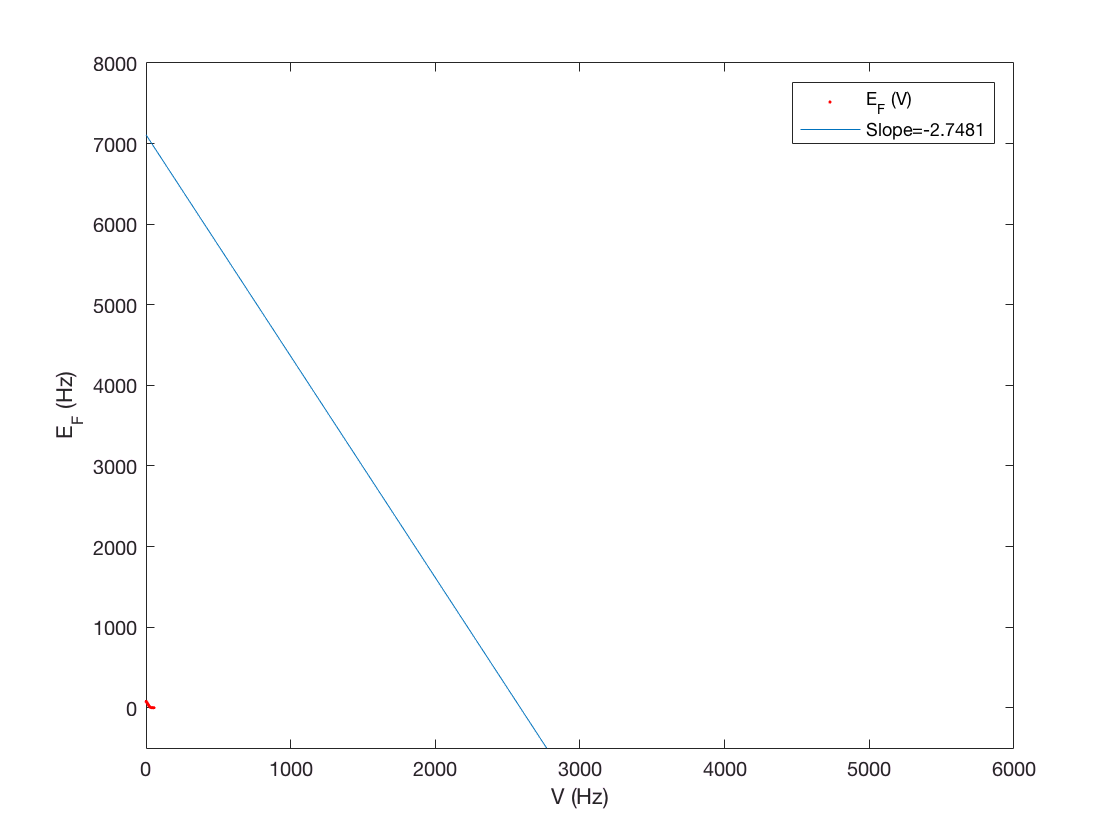

%%Unitary
FitRangeU=1000;
EFfitU=EFU(VsortU<FitRangeU);
VfitU=VsortU(VsortU<FitRangeU);

pU=polyfit(VfitU,EFfitU,1);
EFlineU=polyval(pU,VsortU);
plot(Vhz,EFhz,'r.','DisplayName','E_F (V)');
xlim([0,6000]);ylim([-500,8000]);
hold on
plot(VsortU,EFlineU,'DisplayName',['Slope=',num2str(pU(1))]);
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');
legend('show');

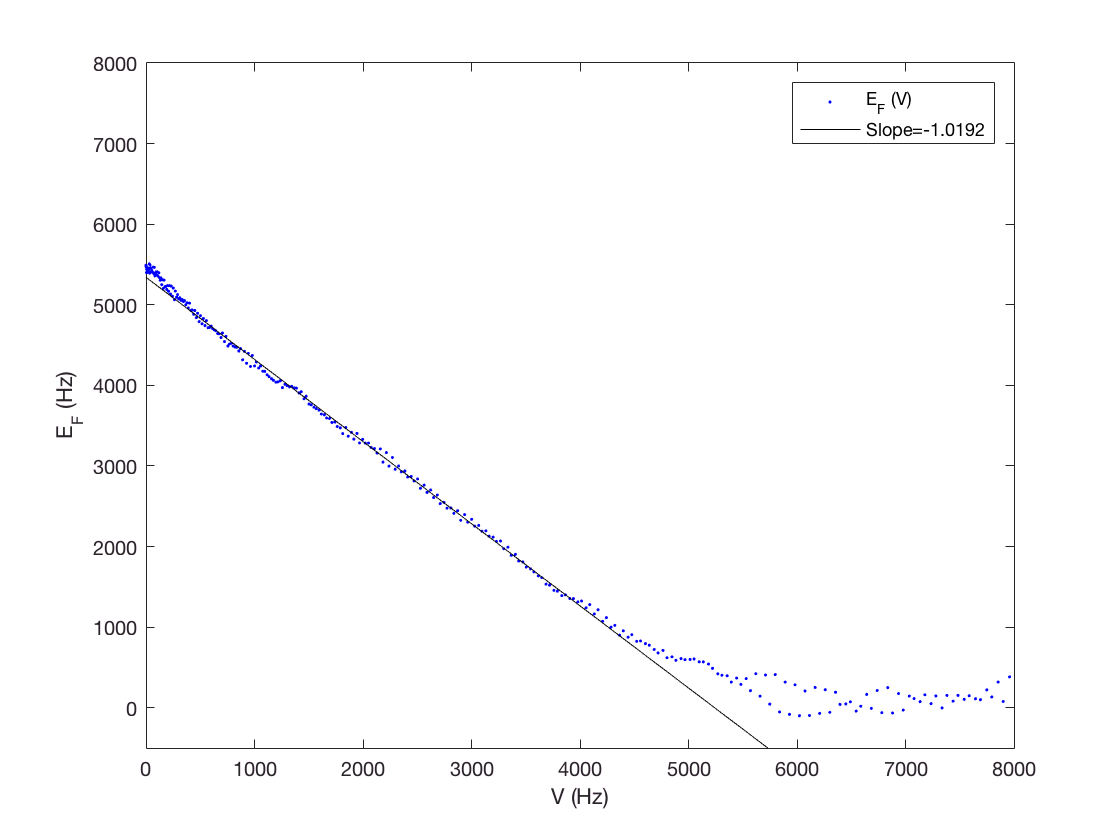


%%
FitRangePolarized1=1800;
FitRangePolarized2=4000;
Mark1=(VsortS1<FitRangePolarized2);
Mark2=(VsortS1>FitRangePolarized1);
Mark=Mark1 & Mark2;
EFfitS1=EFS1(Mark);
VfitS1=VsortS1(Mark);

pS1=polyfit(VfitS1,EFfitS1,1);
EFlineS1=polyval(pS1,VsortS1);
plot(VsortS1,EFS1,'b.','DisplayName','E_F (V)');
xlim([0,8000]);ylim([-500,8000]);
hold on
plot(VsortS1,EFlineS1,'k','DisplayName',['Slope=',num2str(pS1(1))]);
xlabel('V (Hz)');ylabel('E_F (Hz)');
legend('show');
hold off

Plot the Final Figure

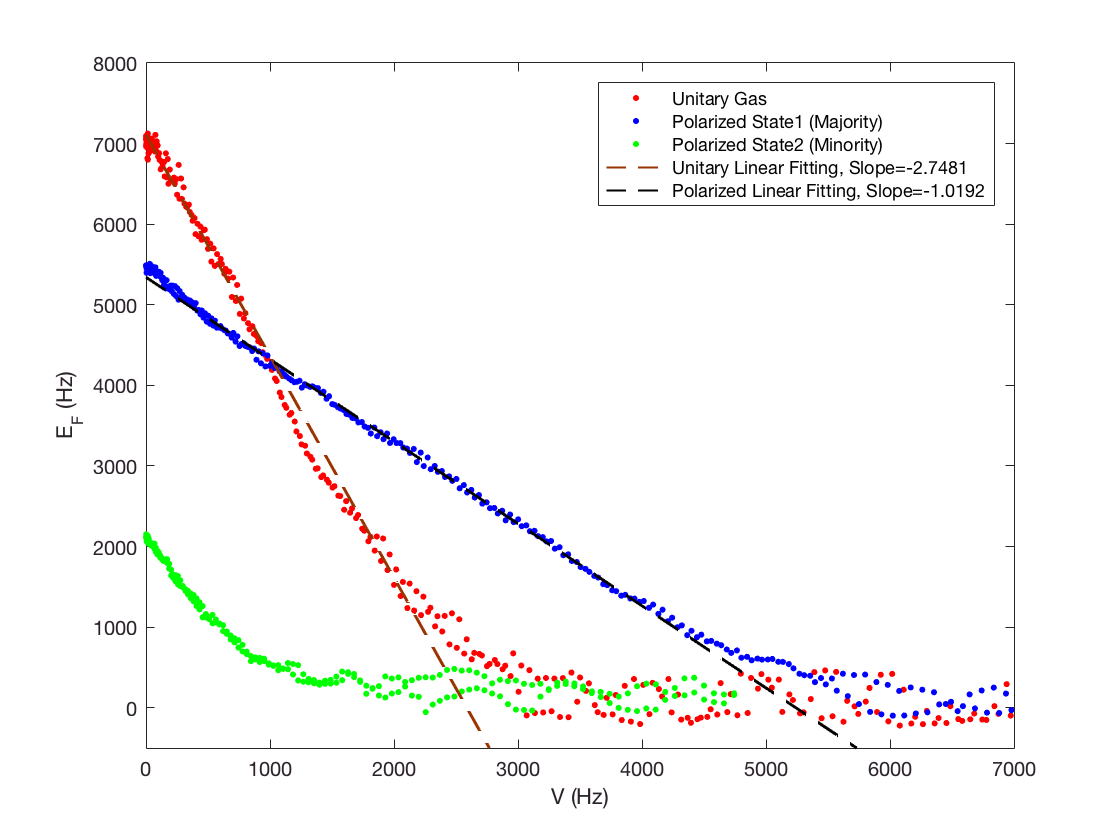

plot(VsortU,EFU,'r.','DisplayName','Unitary Gas','MarkerSize',15);
hold on
plot(VsortS1,EFS1,'b.','DisplayName','Polarized State1 (Majority)','MarkerSize',15);
plot(VsortS2,EFS2,'g.','DisplayName','Polarized State2 (Minority)','MarkerSize',15);
xlim([0,7000]);
plot(VsortU,EFlineU,'--','color',[0.6,0.2,0],'DisplayName',['Unitary Linear Fitting, Slope=',num2str(pU(1))],'LineWidth',1);
plot(VsortS1,EFlineS1,'k--','DisplayName',['Polarized Linear Fitting, Slope=',num2str(pS1(1))],'LineWidth',1);
legend('Show')
ylim([-500,8000]);
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');

Try how different the slope would be if we changing the fitting range.

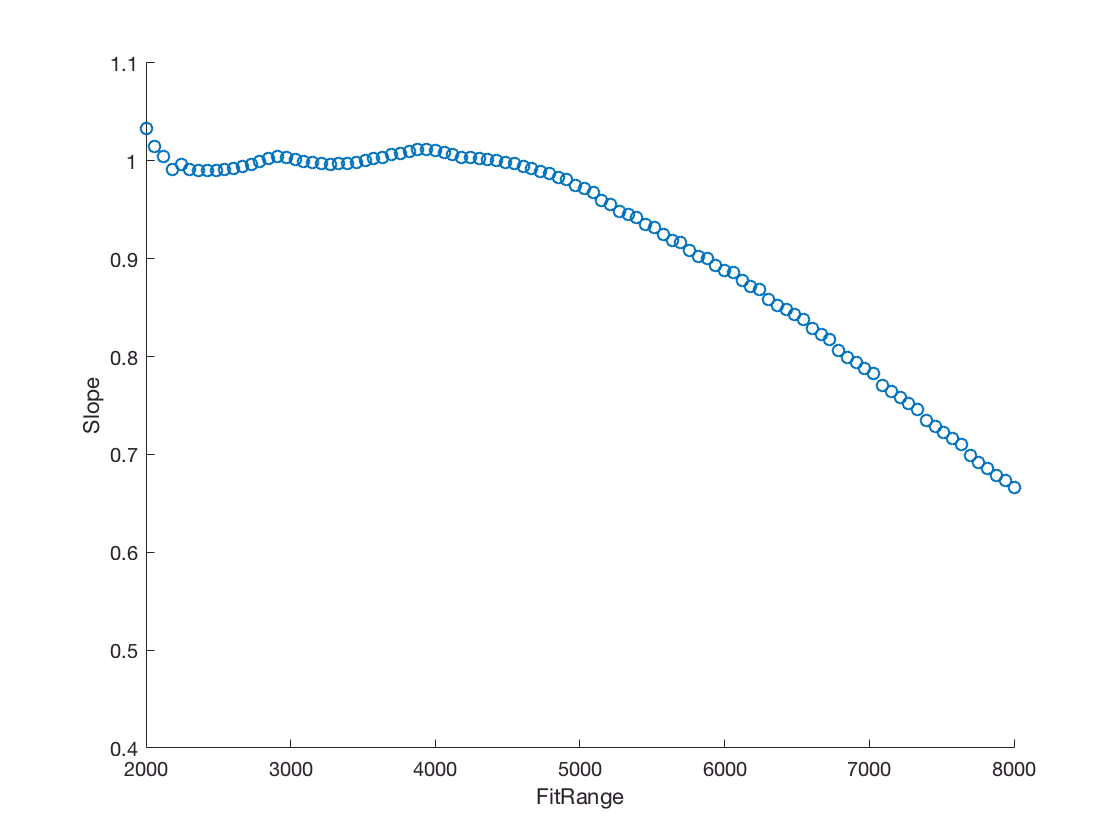

FitRangePolarized1=1200;
FitRangeP2=linspace(2000,8000,100);
N=length(FitRangeP2);
slope=FitRangeP2*0;
Mark2=(VsortS1>FitRangePolarized1);
for i=1:N
    Mark1=(VsortS1<FitRangeP2(i));
    Mark=Mark1 & Mark2;
    EFfit=EFS1(Mark);
    Vfit=VsortS1(Mark);
    ptemp=polyfit(Vfit,EFfit,1);
    slope(i)=ptemp(1)*(-1);
end

scatter(FitRangeP2,slope);
xlabel('FitRange');ylabel('Slope')
ylim([0.4,1.1])

Try the simulated polarized data:

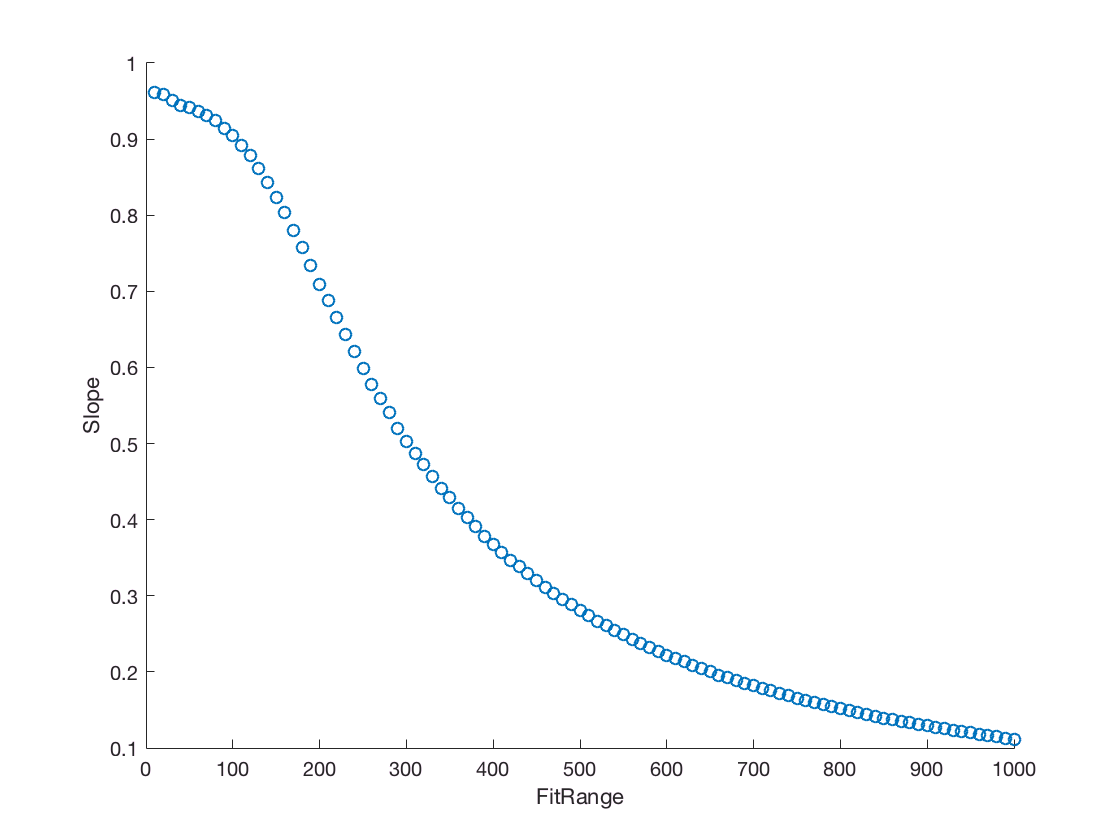

load('polarized_simulated_T0_03_noise_hires.mat');
Zsim=y_vec;
Vsim=0.5*mli*omega^2*Zsim.^2;
nsim=n_simulated;

[Vsortsim,B]=sort(Vsim);
nsortsim=nsim(B);
EFsim=real(hbar^2*(6*pi^2*nsortsim).^(2/3)/(2*mli));

EFsim=EFsim/hh;Vsortsim=Vsortsim/hh;
mark=Vsortsim<1000;
EFsimfit=EFsim(mark);
Vsimfit=Vsortsim(mark);

FitRangeSim=linspace(10,1000,100);
N=length(FitRangeSim);
slope=FitRangeSim*0;
for i=1:N
    Vfit=Vsimfit(Vsimfit<FitRangeSim(i));
    EFfit=EFsimfit(Vsimfit<FitRangeSim(i));
    ptemp=polyfit(Vfit,EFfit,1);
    slope(i)=ptemp(1)*(-1);
end

scatter(FitRangeSim,slope);
xlabel('FitRange');ylabel('Slope')